On a un signal x(t) aléatoire et stationnaire. On peut en calculer la DSP mais celle-ci ne convergera pas si l'on prend le signal en entier $S_{\mathrm{xx}} \left(f\right)=E\left\lbrack {\mathrm{lim}}_{T->\infty } \frac{{|X_T \left(f\right)|}^2 }{T}\right\rbrack =\mathrm{DSP}$

On découpe alors le signal en plusieurs morceaux afin de pouvoir calculer cette espérance. Il faut alors trouver le juste milieu entre résolution fréquentielle et nombre de données. Si l'on découpe notre signal en L morceaux, Chaque morceau composé de N échantillons. 


$$\begin{array}{l}
T_{\mathrm{total}} =L\ldotp T=L\ldotp N\ldotp T_e \\
\Delta f=\frac{1}{N\ldotp T_e }=\frac{f_e }{N}
\end{array}$$


Dans notre cas deux fréquences doivent être identifiées : f_o et f_i. Il nous faut donc une résolution R suffisante.$\Delta f=\frac{f_e }{N}=\frac{R}{10}$ avec $R=\frac{f_i }{f_o }$.

close all; 
clear all;
%% Data
Date = ["2014-03-26" "2014-04-01" "2014-04-03" "2014-04-09" "2014-04-24" "2014-04-28"];
%Date = ["2014-03-26"];
color_p = ['r', 'b', 'g', 'k', 'm', 'c'];
color_p = color_p(1:length(Date));
f_meca = [{'lss'}, {'hss'}];
f_elec = [{'i1'}]

f_elec = 1×1 cell array
    {'i1'}


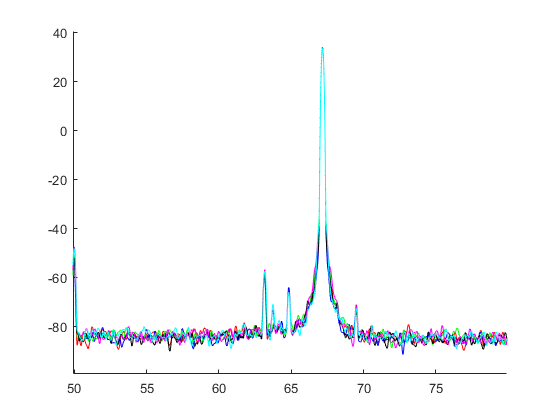

f_cur = f_elec;
nFields = length(f_cur);
dataDir = 'E:\3a_sicom_eeh\Project_wind_turbine\data\';
Legend=cell(length(Date),1);
integ = zeros(1,length(Date));

fend = 1.9531e+04;
f1 = 66/fend;
f2 = 68/fend;

%% Values
fo = 7.65/3; %Prendre plutot val moyenne frequence
fi = 10.35/3; %Prendre plutot val moyenne frequence
R = fi-fo;
df = R/10;

for p = 1:length(Date)
    date = Date(p);
    allFiles = dir(fullfile(dataDir, date + "*"));
    old_data = load(strcat(dataDir, allFiles(1).name));
    %merge fields to create one large data srtuture
    for i = 2:length(allFiles)
        data = load(strcat(dataDir, allFiles(i).name));
        f = fieldnames(old_data);
        for j = 1:length(f)
            data.(f{j}) = old_data.(f{j});
        end
        old_data = data;
    end
    data_meca = [];
    for j = 1:nFields
        data_meca.(f_cur{j}) = data.(f_cur{j});
    end

    for k = 1:nFields
        cur_data = data_meca.(f_cur{k});
        cur_raw = cur_data.rawData;
        fs = cur_data.fs;
        nsamples = length(cur_raw);
        
        %% Values
        fe = fs;
        N = round(fe/df);
        %Nb_seg = int(nsamples/N);
        
        %%Variable a def
        Overlap = round(3*N/4);
        
        
        cur_raw = cur_raw-mean(cur_raw);
        [res,f]= pwelch(cur_raw,blackman(N),Overlap,10*N,fe);
        %outb = filter(b, 1, cur_raw);
        %interv = [min(find(f>64)):min(find(f>65)) min(find(f>69)):min(find(f>70))];
        %res = res(interv);
        
            win1_Hz = min(find(f > 67.17 - 3.45));
    win1_Hz_m = win1_Hz - min(find(f > 0.1));
    win1_Hz_M = win1_Hz + min(find(f > 0.1));
    win1vec_Hz = [win1_Hz_m:win1_Hz_M];
    win2_Hz = min(find(f > 67.17 + 3.45));
    win2_Hz_m = win2_Hz - min(find(f > 0.1));
    win2_Hz_M = win2_Hz + min(find(f > 0.1));
    win2vec_Hz = [win2_Hz_m:win2_Hz_M];
    
    integ(p) = sum(res(win1vec_Hz)) + sum(res(win2vec_Hz));
        figure(1);
        hold on;
        subplot(1,nFields,k)

        Legend{p} = Date(p);
        plot(f, 20 * log10(res), color_p(p));
        %plot(outb)
        xlim([50 80]);
    end   
end

integ = zeros(1,length(Date));
figure,
for p = 1:length(Date)
    win1_Hz = min(find(f > 67.17 - 3.45));
    win1_Hz_m = win1_Hz - min(find(f > 0.1));
    win1_Hz_M = win1_Hz + min(find(f > 0.1));
    win1vec_Hz = [win1_Hz_m:win1_Hz_M];
    win2_Hz = min(find(f > 67.17 + 3.45));
    win2_Hz_m = win2_Hz - min(find(f > 0.1));
    win2_Hz_M = win2_Hz + min(find(f > 0.1));
    win2vec_Hz = [win2_Hz_m:win2_Hz_M];
    
    integ(p) = sum(res(win1vec_Hz)) + sum(res(win2vec_Hz));
    plot(integ * ones(1,5)), hold on
end

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

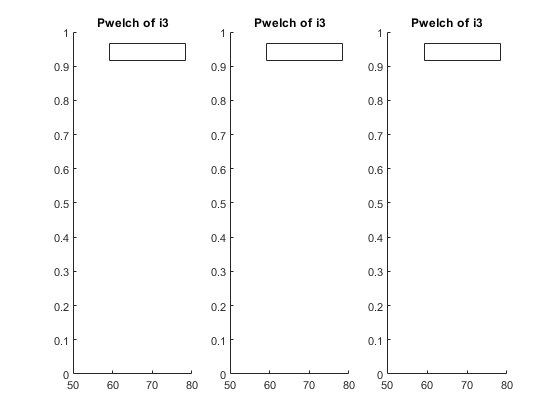



figure(1)
for i = 1:nFields
    subplot(1,nFields,i)
    legend(Legend)
    tit = convertCharsToStrings(f_cur{k});
    title("Pwelch of "+tit)
end

cur_data = data_meca.(f_cur{1});
cur_raw = cur_data.rawData;
cur_raw = cur_raw-mean(cur_raw);
[res1,f]= pwelch(cur_raw,N,Overlap,10*N,fe);



cur_data = data_meca.(f_cur{2});
cur_raw = cur_data.rawData;
cur_raw = cur_raw-mean(cur_raw);
[res2,f]= pwelch(cur_raw,N,Overlap,10*N,fe);


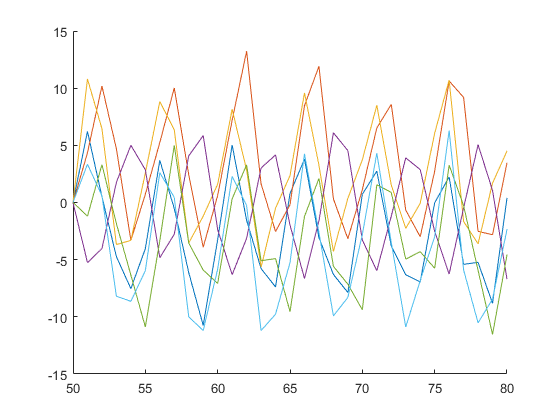



figure
fend = 1.9531e+04;
f1 = 66/fend;
f2 = 68/fend;
%b = fir1(100, [f1 f2], 'stop');


Date = ["2014-03-26" "2014-04-01" "2014-04-03" "2014-04-09" "2014-04-24" "2014-04-28"];
dataDir = 'E:\3a_sicom_eeh\Project_wind_turbine\data\';
f_elec = [{'i1'}];
f_cur = f_elec;
nFields = length(f_cur);
for p = 1:length(Date)
    date = Date(p);
    allFiles = dir(fullfile(dataDir, date + "*"));
    old_data = load(strcat(dataDir, allFiles(1).name));
    %merge fields to create one large data srtuture
    for i = 2:length(allFiles)
        data = load(strcat(dataDir, allFiles(i).name));
        f = fieldnames(old_data);
        for j = 1:length(f)
            data.(f{j}) = old_data.(f{j});
        end
        old_data = data;
    end
    data_meca = [];
    for j = 1:nFields
        data_meca.(f_cur{j}) = data.(f_cur{j});
    end
    
    cur_data = data_meca.(f_cur{1});
    cur_raw = cur_data.rawData;
    fs = cur_data.fs;
    nsamples = length(cur_raw);
        
    %% Values
    fe = fs;
    %Nb_seg = int(nsamples/N);
    
    %%Variable a def

    cur_raw = cur_raw-mean(cur_raw);
    outb = filter(b, 1, cur_raw);
    hold on
    plot(outb)
    xlim([50 80])
end

Legend=cell(length(Date),1)

Legend = 6×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
